# Paraboloidal wave vs spherical wave

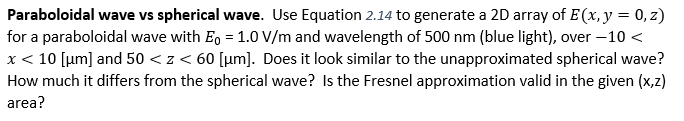

All lengths are in [m].

clear

E0 = 1.0;
lam = 500e-9;
k = 2*pi/lam

k = 1.2566e+07

## Visualize E(x,z) of the paraboloidal wave (approximation).

2D grid of (x,z)

dx = 0.1e-6;  % 0.1 um, usually 1/100 of the area to be sampled, in the order of magnitude
x = -10e-6:dx:10e-6;  nx = length(x);
z = 50e-6:dx:60e-6;  nz = length(z);

[gx,gz] = ndgrid(x,z);
size(gx)

ans =    201   101


2D array of E(x,z)

Here, we will use the complex representation in building the array and take its real part when visualizing the field.

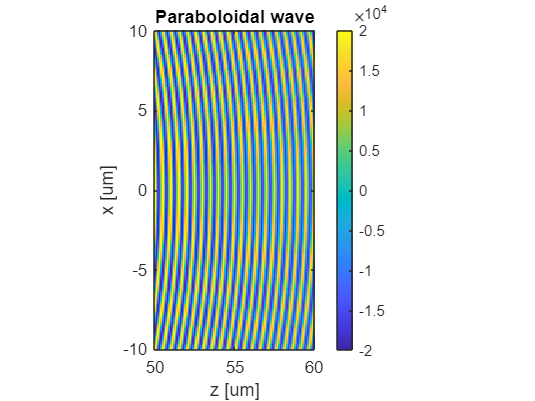

E = E0 ./ gz .* exp(1i * k./(2*gz) .* (gx.^2+0.^2) ) .* exp(1i * k * gz);

figure
imagesc(z*1e6, x*1e6, real(E))
colorbar
ax = gca;
ax.YDir = "normal";
ax.DataAspectRatio = [1 1 1];
ax.XLabel.String = "z [um]";
ax.YLabel.String = "x [um]";
ax.Title.String = "Paraboloidal wave";

## Visualize E(x,z) of the original spherical wave.

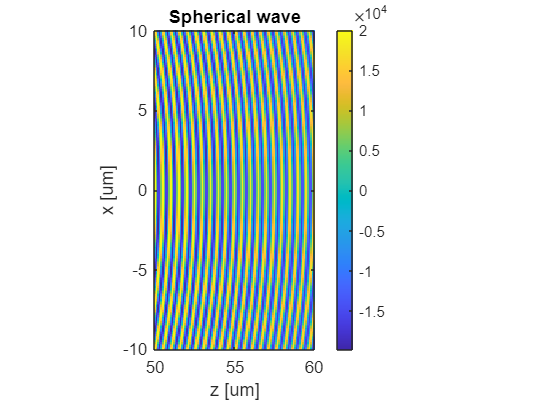

r = sqrt(gx.^2 + 0^2 + gz.^2);
Esp = E0 ./ r .* exp(1i * k * r);

figure
imagesc(z*1e6, x*1e6, real(Esp))
colorbar
ax = gca;
ax.YDir = "normal";
ax.DataAspectRatio = [1 1 1];
ax.XLabel.String = "z [um]";
ax.YLabel.String = "x [um]";
ax.Title.String = "Spherical wave";

Quantify the difference (relative to the original wave).

mean2(abs(E-Esp).^2) / mean2(abs(Esp).^2)

ans = 0.0012

## Check the Fresnel approximation validity.

$\frac{\rho^4}{4 \lambda z^3}$ should be much smaller than 1. 

xMax = max(x);
zMin = min(z);
xMax^4/4/lam/zMin^3

ans = 0.0400